# Scenario Generation

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

[Scenario generation](https://www.mathworks.com/help/uav/ug/uav-scenario-tutorial.html) for UAV modeling is the process of systematically creating virtual flight environments and mission conditions in which a UAV’s dynamics, sensors, and autonomy algorithms can be simulated, tested, and validated. Rather than flying a single nominal trajectory, scenario generation defines what the UAV encounters: terrain and obstacles, weather, other vehicles, sensor configurations, failures, and mission objectives, all within a repeatable simulation framework. [](https://www.mathworks.com/products/uav.html)

At a technical level, a UAV scenario specifies:

- **The environment** (terrain, buildings, obstacles, no‑fly zones, weather)

- **Platforms and trajectories** (UAV type, initial state, waypoints, timing)

- **Sensors and noise models** (IMU, GPS, camera, LiDAR, failures or dropouts)

- **Events and constraints** (wind gusts, obstacle appearance, GPS denial, mission triggers) Tools such as the [`uavScenario`](https://www.mathworks.com/help/uav/ref/uavscenario.html) framework in the UAV Toolbox use these elements to generate **synthetic sensor data and ground‑truth states** for algorithm development and testing.

The purpose of scenario generation is to support verification, validation, and learning without risky or expensive flight testing. By varying parameters or randomizing conditions, engineers can explore edge cases, rare events, and safety‑critical situations that are difficult to reproduce in real flight. This is essential for autonomy, where performance depends not on one flight, but on robustness across a wide operating envelope. With the UAV Toolbox, it is possible to generate flight scenarios of different fidelities, which are more suitable for different kinds of applications.

We have already seen an example of a [quadcopter built in Simscape Multibody](matlab:open('.\QuadcopterFromFEX.mlx')). This type of detailed physical model is useful for engineers working on the quadcopter's design. However, it might not be very relevant for designing the Guidance & Navigation algorithms, which only need a low-fidelity model. Alternatively, other engineers may want to focus on photorealistic simulations for developing Perception algorithms. 

[**UAV Scenario Tutorial**](https://www.mathworks.com/help/uav/ug/uav-scenario-tutorial.html)

In this example, see how to generate a cuboidal (built out of boxes) model of a city to model a simple lidar point cloud sensor: 

openExample('uav/UAVScenarioTutorialExample')
 

**When you are done**

ReturnHere
 

This type of model can be used for discovering waypoints between points using a path planning algorithm such as [RRT](https://en.wikipedia.org/wiki/Rapidly_exploring_random_tree) or similar. This is shown in the [**Plan Minimum Snap Trajectory for Quadrotor example**](https://www.mathworks.com/help/uav/ug/plan-minimum-snap-trajectory-for-quadrotor.html), where a quadcopter is flying through a low-resolution city map:

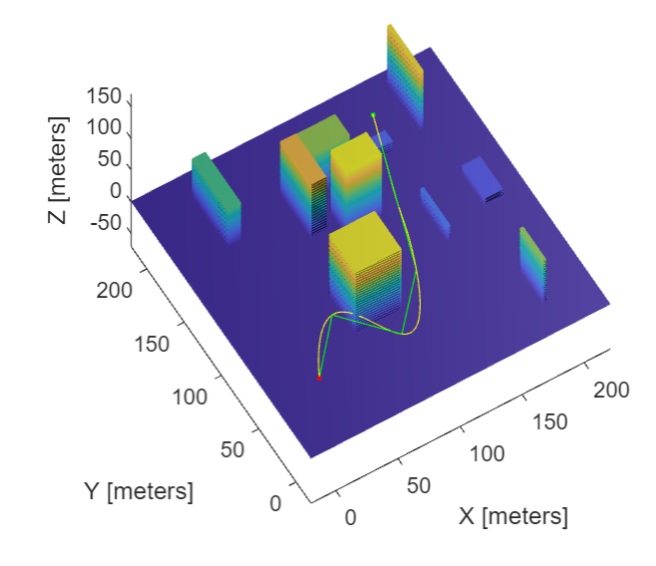

openExample('uav/PlanMinimumSnapTrajectoryForQuadrotorExample')
 

**When you are done**

ReturnHere
 

**Photorealistic Simulation with Unreal Engine (For Sensor Models)**

For creating more realistic-looking models to use for sensor simulations, we can utilize co-simulation with [Unreal Engine](https://www.mathworks.com/help/driving/unreal-engine-scenario-simulation.html). 

- Run the example here to see a Quadcopter flying through a photorealistic 'city block' simulation in the [Simulate Simple Flight Scenario and Sensor in Unreal Engine Environment](https://www.mathworks.com/help/uav/ug/simulate-a-simple-flight-scenario-and-sensor-in-3d-environment.html).

openExample('uav/SimpleFlightAndSensorInUE4Example')
 

**When you are done**

ReturnHere
 

- A full photorealistic simulation of a [UAV package delivery system](https://www.mathworks.com/help/uav/ug/uav-package-delivery.html) can be found here with varying levels of model fidelity and connection with QGroundControl software: 

openExample('uav/UAVPackageDeliveryExample')
 

**When you are done**

ReturnHere
 

## Further Exploration

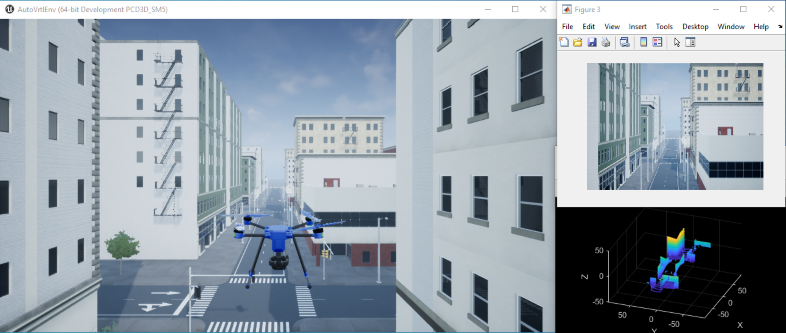

Perception Algorithms and Deep Learning are beyond the scope of this course, as the focus here is primarily on modeling and simulation. However, you can explore the[ Depth and Semantic Segmentation Visualization Using Unreal Engine Simulation example](https://www.mathworks.com/help/driving/ug/visualize-depth-semantic-segmentation-3d-simulation.html) to see how to use the generated sensor data to build a depth and semantic segmentation map that helps the UAV fly autonomously.

openExample('uav/DepthAndSegmentationVisualizationUsingUE4SimulationExample')
 

**When you are done**

ReturnHere
 

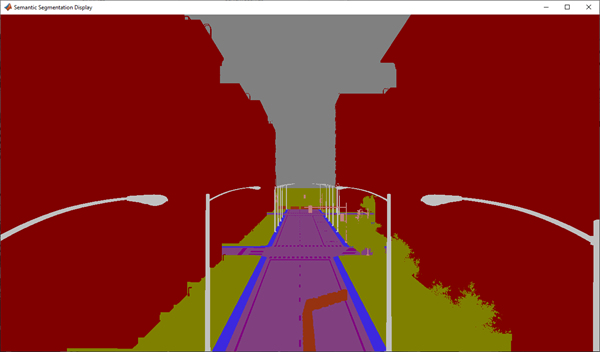

To learn more about Deep Learning and Computer Vision, see: 

- [Deep Learning Toolbox Documentation](https://www.mathworks.com/help/deeplearning/index.html)

- [Computer Vision Toolbox Documentation](https://www.mathworks.com/help/vision/index.html)

- [LIDAR Toolbox Documentation](https://www.mathworks.com/help/lidar/index.html)

- Online Self-Paced Courses on [MATLAB Academy](https://matlabacademy.mathworks.com/#getting-started)

- [Computer Vision Basics](https://www.mathworks.com/matlabcentral/fileexchange/180661-computer-vision-basics) courseware

For more examples around UAVs, see: [**UAV Toolbox Examples**](https://www.mathworks.com/help/uav/examples.html)

**When you are done**

ReturnHere
 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

function ReturnHere()
curloc = matlab.desktop.editor.getActiveFilename;
if contains(curloc,"Scripts")
    rootdir = extractBefore(curloc,filesep+"Scripts");
elseif contains(curloc,"InstructorResources")
    rootdir = extractBefore(curloc,filesep+"InstructorResources");
else
    error("Unexpected location: " + curloc)
end
cd(rootdir)
end